# What's New in Simulink R2024a?

MATLAB R2024a is now available, and a lot of new important features have been added to Simulink. Here is my top 5.

## Simulation object

Using the [Simulation object](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulation.html), you can programmatically run a simulation step by step. You can execute the simulation one step at a time, step for a number of steps or up to a specific time. Here is an example where I simulate the simulation up to t=18.5 seconds, then I change the value of variable `k` and continue the simulation until the stop time:

mdl = 'vdpX';
sm = simulation(mdl);
% Run the first part of the simulation with k=0.2
sm.setVariable('k',0.2);
step(sm,PauseTime=18.5);
% Run the second half with k=1.5
sm.setVariable('k',1.5);
step(sm,PauseTime=40);
out = terminate(sm);

## Design Study

The new [Design Study API](https://www.mathworks.com/help/releases/R2024a/simulink/slref/designstudy.html) provides a layer on top of [parsim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/parsim.html) and [batchsim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/batchsim.html) to improve scalability. Instead of creating an array of [Simulink.SimulationInput](http://simulink.simulationinputhttps//www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulationinput.html) objects, you specify arrays of values to be simulated, and how they should be combined. Here is a simple example where I simulate a mass-spring-damper system for different mass and damping values. 

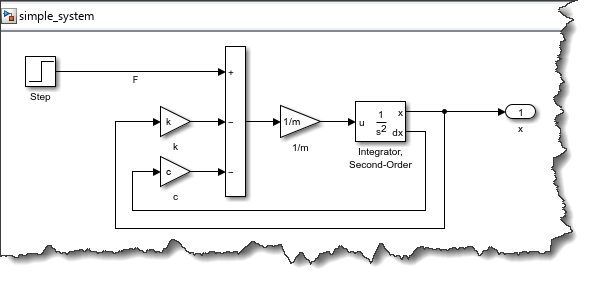

I specify 5 mass values and 5 damping values, and simulate an exhaustive combination for a total of 25 simulation

mdl = 'simple_system';
kVar = simulink.multisim.Variable('c',1:5);
cVar = simulink.multisim.Variable('m',1:5);
fullSpace = simulink.multisim.Exhaustive([kVar cVar]);
myDesignStudy = simulink.multisim.DesignStudy(mdl, fullSpace);
outH = parsim(myDesignStudy,'ShowProgress','Off','UseFastRestart','on');
out = fetchOutputs(outH);

## Specifying Variant Configurations using a simulation input object

A new `VariantConfiguration` property has been added to the Simulink.SimulationInput object. Here is an example code where I get the variant configuration data for a model and run one simulation per available configuration:

mdl = 'sldemo_variant_subsystems';
load_system(mdl);
load('variantConfigs.mat'); % load pre-saved variant configuration data
vcd = Simulink.VariantManager.getConfigurationData(mdl);
N = length(vcd.Configurations);
in(1:N) = Simulink.SimulationInput(mdl);
for i = 1:N
    in(i) = in(i).setVariantConfiguration(vcd.Configurations(i).Name);
end
out = sim(in,'ShowProgress','off');

## Preserve alignment when moving and resizing blocks

When selecting a block, you might notice a light green highlighting on connections and blocks around it. This means that we have detected that those connections and blocks should likely move with the blocks.

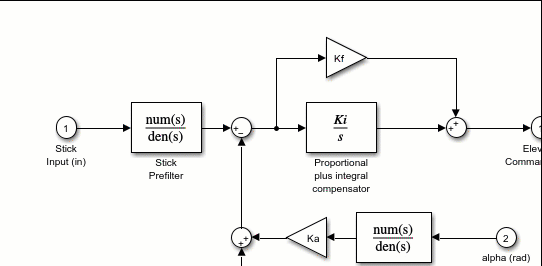

Same works with resizing:

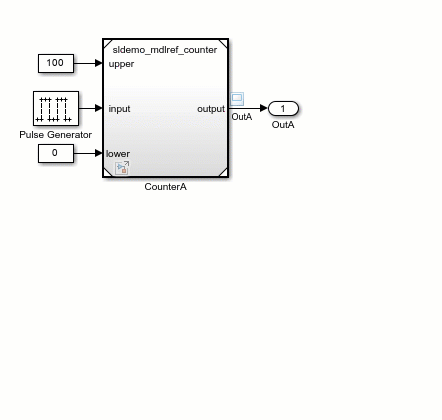

## Simplified Mechanism to access Data Dictionaries

Before R2024a, if you wanted to programmatically change the value of a parameter stored in a data dictionary, you had to write code like this:

myDictionaryObj = Simulink.data.dictionary.open('simplesystemDD.sldd');
dDataSectObj = getSection(myDictionaryObj,'Design Data');
kObj = getEntry(dDataSectObj,'k');
k = getValue(kObj);
k = k+1;
setValue(kObj,k);

In R2024a, you can simple [`connect`](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.data.connect.html) to a data dictionary and interact with it using the dot operator.

h = Simulink.data.connect('simplesystemDD.sldd');
h.k = h.k+1;

## Now it's your turn

Give a look at the [Simulink release notes for R2024a](https://www.mathworks.com/help/releases/R2024a/simulink/release-notes.html). Let us know your favorite feature and which ones you would like to see highlighted on this blog.

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_04_10_Whats_New_R2024a/2024_04_10_Whats_New_R2024a.prj)